clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_clock+4, 1);
y0(n_clock+1) = 1;
y0(n_clock+4) = 100;

tmax = 1000;
tspan = 0:0.1:tmax;

t_V = zeros(4, 1);  % CT0, CT6, CT12, CT18
for i = 1:4
    t_V(i) = 500 + 6 * (i - 1);
end

y = zeros(length(tspan), n_clock+4, 5);
parfor i = 1:4
    [~, y(:, :, i)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(i));
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).


par_scg(6) = 100000;
[~, y(:, :, 5)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(1));
y = real(y);

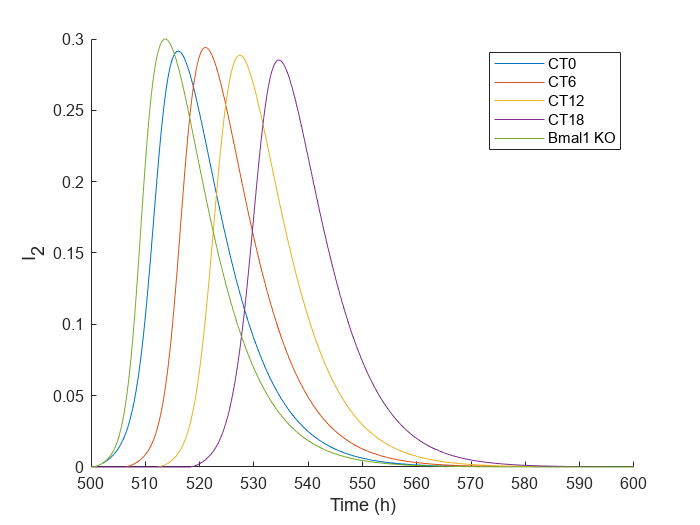

% plot I2
figure; hold on;
I_tot = zeros(length(tspan), 5);
for i = 1:5
    plot(tspan, y(:, n_clock+3, i));
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('I_2');
legend('CT0', 'CT6', 'CT12', 'CT18', 'Bmal1 KO');
hold off;

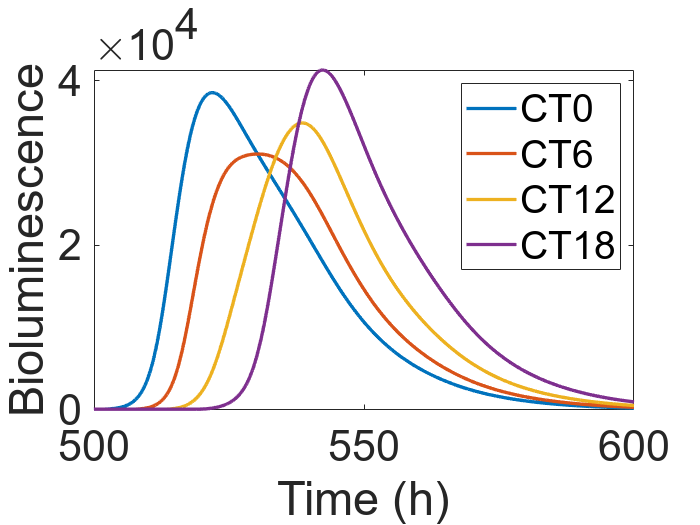

% Plot bioluminescence (B)
figure; hold on; set(gca,'Fontsize',26); box on;
for i = 1:4
    plot(tspan, y(:, n_clock+4, i), 'LineWidth', 2);
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('Bioluminescence');
legend('CT0', 'CT6', 'CT12', 'CT18');
hold off;

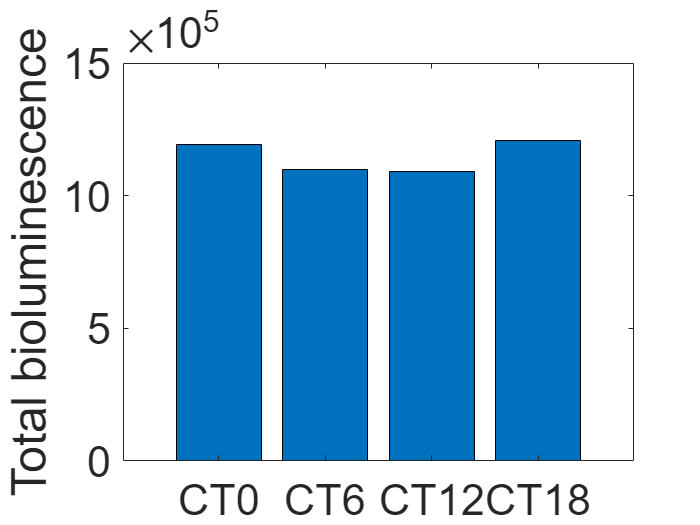

% calculate some related values of boiluminescence curve
biolu_tot = zeros(1, 5);
half_t = zeros(2, 5); % left, right

for i = 1:4
    B = y(:, n_clock+4, i);
    [peak_var, peak_idx] = max(B);
    B_left = B(1:peak_idx);
    B_right = B(peak_idx+1:end);

%     biolu_tot(i) = trapz(tspan(1:peak_idx), B_left) / trapz(tspan, B);
    biolu_tot(i) = trapz(tspan, B);
    [~, half_t(1, i)] = min(abs(B_left - peak_var / 2));
    [~, half_t(2, i)] = min(abs(B_right - peak_var / 2));

    % transfer to real time t
    half_t(1, i) = (half_t(1, i) - 1) ./ 10 - t_V(i);
    half_t(2, i) = (half_t(2, i) + peak_idx - 1) ./ 10 - t_V(i);
end

bar_name = categorical({'CT0', 'CT6', 'CT12', 'CT18'});
bar_name = reordercats(bar_name, {'CT0', 'CT6', 'CT12', 'CT18'});

bar(bar_name, biolu_tot(1:4)); ylabel('Total bioluminescence');
set(gca,'Fontsize',26); box on;

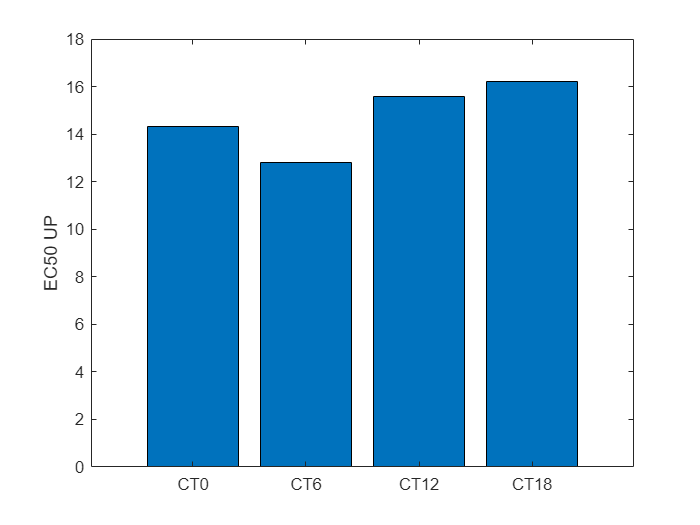

bar(bar_name, half_t(1, 1:4)); ylabel('EC50 UP');

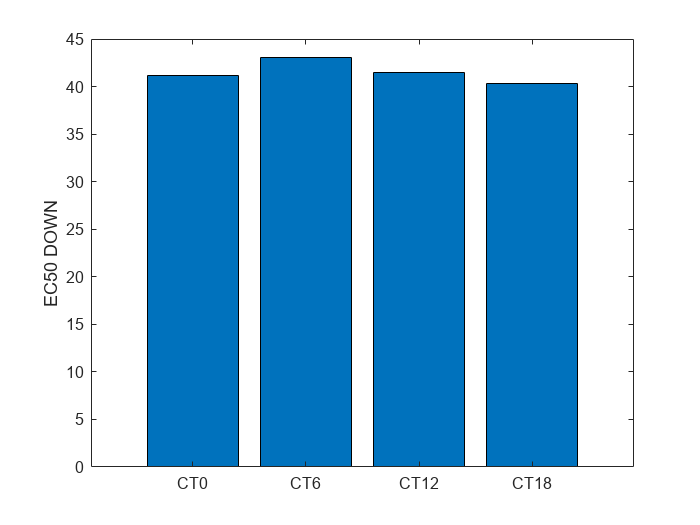

bar(bar_name, half_t(2, 1:4)); ylabel('EC50 DOWN');

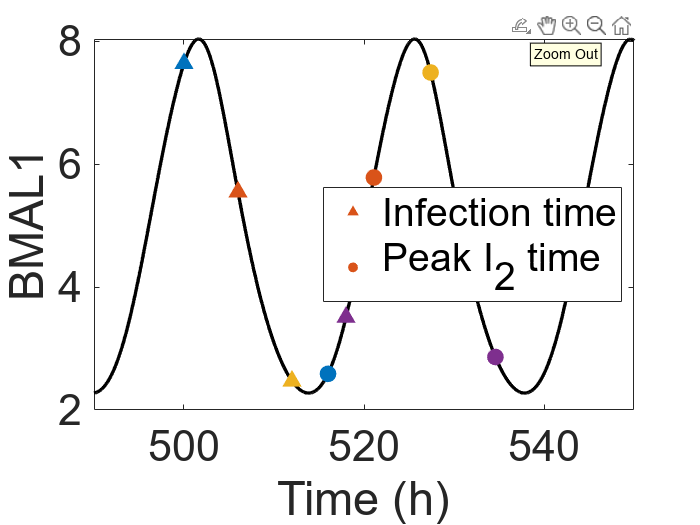

% Plot BMAL1 and phases of infection and peak time of I2
peak_idx_I2 = zeros(4, 1);    
for i = 1:4
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end
% half_t_real = zeros(4, 1);
% for i = 1:4
%     half_t_real(i) = half_t(1, i) + t_V(i);
% end
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 2);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560];
scatter(t_V, y(t_V .* 10 + 1, 10, 1), sz, c, '^', 'filled');
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 10, 1),  sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('BMAL1');
legend('', 'Infection time', 'Peak I_2 time');
hold off;

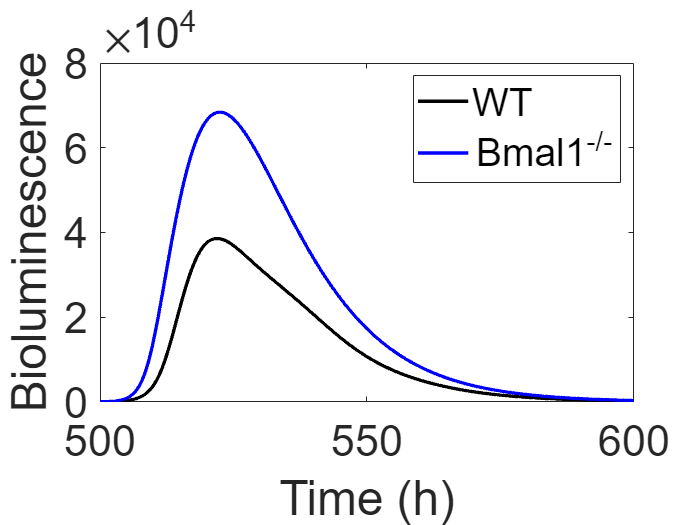

% Plot bioluminescence (B) clock ko
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, n_clock+4, 1), 'LineWidth', 2, 'Color', 'k');
plot(tspan, y(:, n_clock+4, 5), 'LineWidth', 2, 'Color', 'b');
xlim([500 600]);
xlabel('Time (h)'); ylabel('Bioluminescence');
legend('WT', 'Bmal1^{-/-}');
hold off;